# Sample 8-1

## 離散コサイン変換

画像変換の効果

画像処理特論

村松 正吾 

動作確認: MATLAB R2023a

## Discrete cosine transform

Effect of image transforms

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2023a

### 準備

(Preparation)

close all

### 原画像の読込と表示

(Read and display an image)

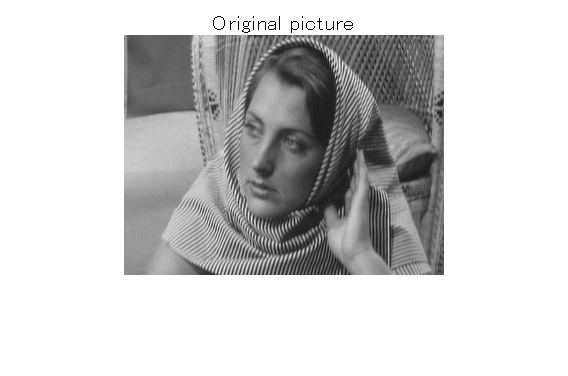

V = rgb2gray(imread('data/barbaraFaceRgb.tif'));
figure(1)
imshow(V)
title('Original picture')

### 2次元ベクトル集合の抽出

(Extraction of a set of 2-D vectors)

水平方向のペアを抽出しデータ行列を生成 (Extract horizontal pairs and generates data matrix)

- 画素配列(pixel array)

            
$$\mathbf{V} = \left(\begin{array}{lllll} v_{0,0} & v_{0,1} & v_{0,2} & \cdots \\ v_{1,0} & v_{1,1} & v_{1,2} & \cdots \\ \vdots & \vdots & \vdots & \ddots \end{array}\right)$$


- データ行列(data matrix)

            
$$\mathbf{X} = \left(\mathbf{x}_1,\mathbf{x}_2,,\cdots \right)＝\left(\begin{array}{lllll} v_{0,0} & v_{0,2} & \cdots & v_{1,0} & \cdots \\ v_{0,1} & v_{0,3} & \cdots & v_{1,1} & \cdots \end{array}\right)$$


nPixels = numel(V);
setOfX = reshape(V.', 2, nPixels/2);

###  変換前の散布図

(Scatter plot before transform)

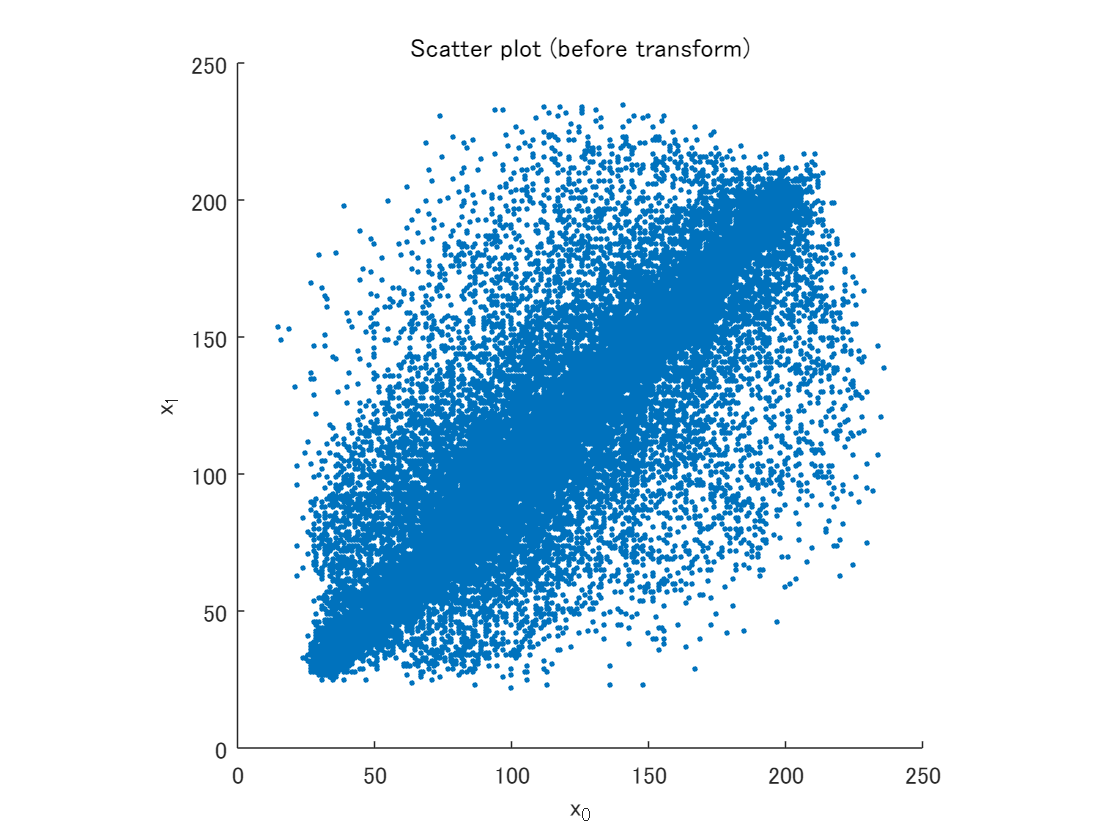

figure(2)
scatter(setOfX(1,:),setOfX(2,:),'.')
axis square
xlabel('x_0')
ylabel('x_1')
title('Scatter plot (before transform)')

標本分散共分散行列と相関係数 (Sample covariance matrix and correlation coefficient)

-  平均ベクトル (mean vector)

            
$$\mathbf{\mu}_\mathrm{x} = E[\mathbf{x}]$$


- 分散共分散行列 (covariance matrix)

            
$$\mathbf{\Sigma}_{\mathrm{xx}} = E\left[(\mathbf{x}-\mathbf{\mu}_{\mathrm{x}})(\mathbf{x}-\mathbf{\mu}_{\mathrm{x}})^T\right]$$


- 相関係数 (correlation coefficient)

            
$$\mathbf{R}_{\mathrm{xx}} = \mathbf{\Lambda}_{\mathrm{x}}^{-\frac{1}{2}}\mathbf{\Sigma}_{\mathrm{xx}}\mathbf{\Lambda}_{\mathrm{x}}^{-\frac{1}{2}}$$


            
$$\mathbf{\Lambda}_{\mathrm{x}} = \left(\begin{array}{ll}\sigma_{\mathrm{x},0}^2 & 0 \\ 0 & \sigma_{\mathrm{x},1}^2\end{array}\right)= \left(\begin{array}{ll}E\left[(x_0-\mu_{\mathrm{x,0}})^2\right] & 0 \\ 0 & E\left[(x_1-\mu_{\mathrm{x},1})^2\right]\end{array}\right)$$


Sxx = cov(double(setOfX.'))

Sxx = 1.0e+03 *

    2.2452    1.8901
    1.8901    2.2206


Rxx = corrcoef(double(setOfX.'))

Rxx =     1.0000    0.8465
    0.8465    1.0000


### 信号変換

(Signal transform)

- 回転行列(rotation matrix)

            
$$\mathbf{A}_{\theta} = \left(\begin{array}{cc} \cos\theta & -\sin\theta \\ \sin\theta & \cos\theta \end{array}\right)$$


- 行列 $\mathbf{A}_\theta$による変換

            
$$\mathbf{y} = \mathbf{A}_\theta\mathbf{x}$$


Atheta = @(theta) [cos(theta) -sin(theta) ; sin(theta) cos(theta)];
theta = -pi/4;
A = Atheta(theta)

A =     0.7071    0.7071
   -0.7071    0.7071


setOfY = A * double(setOfX);

###  変換後の散布図

(Scatter plot after transform)

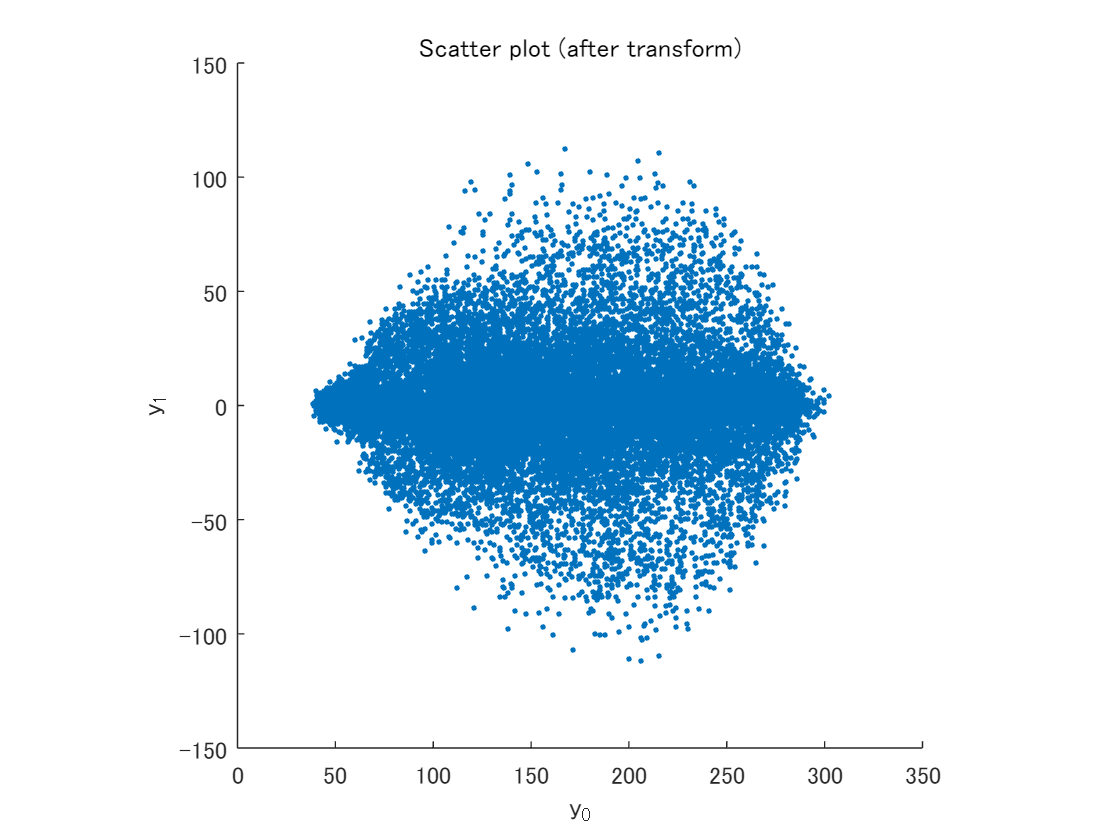

figure(3)
scatter(setOfY(1,:),setOfY(2,:),'.')
axis square
xlabel('y_0')
ylabel('y_1')
title('Scatter plot (after transform)')

標本分散共分散行列と相関係数 (Sample covariance matrix and correlation coefficient)

-  平均ベクトル (mean vector)

            
$$\mathbf{\mu}_\mathrm{y} = E[\mathbf{y}]$$


- 分散共分散行列 (covariance matrix)

            
$$\mathbf{\Sigma}_{\mathrm{yy}} = E\left[(\mathbf{y}-\mathbf{\mu}_{\mathrm{y}})(\mathbf{y}-\mathbf{\mu}_{\mathrm{y}})^T\right]=\mathbf{A}_\theta\mathbf{\Sigma}_\mathrm{xx}\mathbf{A}_\theta^{T}$$


- 相関係数 (correlation coefficient)

            
$$\mathbf{R}_{\mathrm{yy}} = \mathbf{\Lambda}_{\mathrm{y}}^{-\frac{1}{2}}\mathbf{\Sigma}_{\mathrm{yy}}\mathbf{\Lambda}_{\mathrm{y}}^{-\frac{1}{2}}$$


            
$$\mathbf{\Lambda}_{\mathrm{y}} = \left(\begin{array}{ll}\sigma_{\mathrm{y},0}^2 & 0 \\ 0 & \sigma_{\mathrm{y},1}^2\end{array}\right)= \left(\begin{array}{ll}E\left[(y_0-\mu_{\mathrm{y,0}})^2\right] & 0 \\ 0 & E\left[(y_1-\mu_{\mathrm{y},1})^2\right]\end{array}\right)$$


Syy = cov(double(setOfY.'))

Syy = 1.0e+03 *

    4.1230   -0.0123
   -0.0123    0.3428


Ryy = corrcoef(double(setOfY.'))

Ryy =     1.0000   -0.0103
   -0.0103    1.0000


変換後の分散共分散行列と相関係数の非対角成分が変換前よりも小さい。すなわち、相関が低い。(The non-diagonal components of the sample covariance matrix and correlation coefficient after the transform is smaller than before. That is, the correlation becomes lower.)

© Copyright, Shogo MURAMATSU, All rights reserved.